%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%                                                %%%%%%%%
%%%%%%%%          Seyyed Erfan Mohammadi                %%%%%%%%
%%%%%%%%        Homework 4     remove shade             %%%%%%%%
%%%%%%%%            Lecturer:Dr.Shabani                 %%%%%%%%             
%%%%%%%%                                                %%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


First, load all images and save all images to one cell.

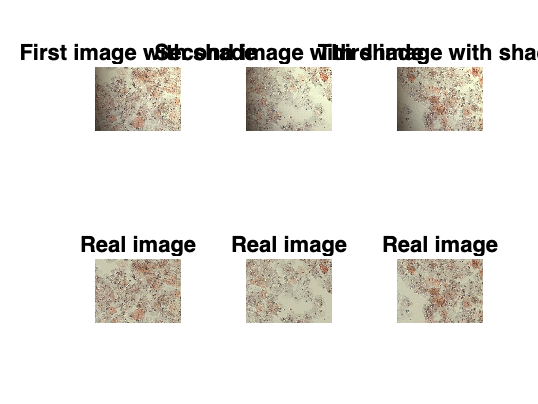

clear all;
close all;
clc;
tic;

image{1}=imread ("000.jpg");
image{2}=imread ("001.jpg");
image{3}=imread ("002.jpg");


image_real{1}=imread ("0000.jpg");
image_real{2}=imread ("0001.jpg");
image_real{3}=imread ("0002.jpg");

subplot(2,3,1);
imshow(image{1});
title('First image with shade');
subplot(2,3,2);
imshow(image{2});
title('Second image with shade');
subplot(2,3,3);
imshow(image{3});
title('Third image with shade');

subplot(2,3,4);
imshow(image_real{1});
title('Real image');
subplot(2,3,5);
imshow(image_real{2});
title('Real image');
subplot(2,3,6);
imshow(image_real{3});
title('Real image');

Second, All channles in all images downsampled for make code faster.

Then use low pass gaussian filter for find shade of all channles.

shade=cell(1,3);
shade_downsample=[];
clf;

for j=1:3
    for i=1:3
downsample_image = imresize(image{j}(:,:,i), 1/40, 'bicubic');

shade_downsample = imgaussfilt(downsample_image,12);

shade{j}(:,:,i)  = imresize(shade_downsample ,[1719 2304], 'bicubic');
    end
end

Plot extracted shade and real shade.

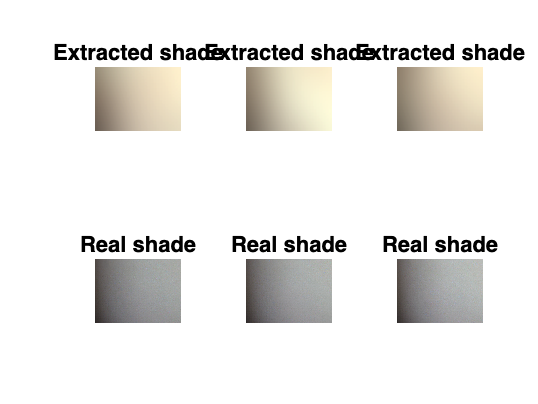

shade_real=cell(1,3);

for i=1:length(image)

mean_shade=mean(mean(mean(double(shade{i}))));
shade{i}=double(shade{i})./(mean_shade);
max_shade=max(max(max(max(double(shade{i})))));
shade{i}=double(shade{i})./double(max_shade);


shade_real{i}=double(image{i})./double(image_real{i});
max_shade=max(max(max(double(shade_real{i}))));
shade_real{i}=double(shade_real{i})./double(max_shade);

subplot(2,length(image),i);
imshow(uint8(255*shade{i}));
title('Extracted shade');
subplot(2,length(image),i+3);
imshow(uint8(255*shade_real{i}));
title('Real shade');
end

Now, The shade diminish from images with division.

For plotting,all images and shades normalized.

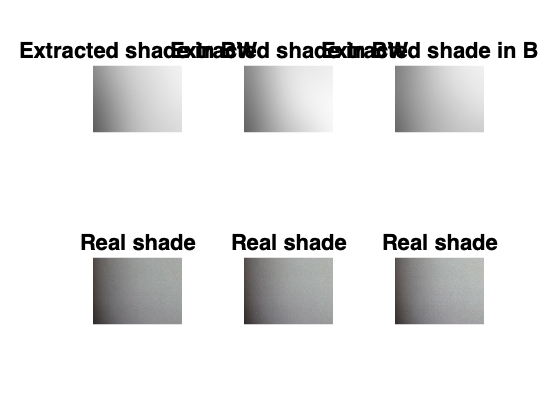

shade_gray=cell(1,3);
new_image=cell(1,3);
for i=1:length(image)
shade_gray{i}=rgb2gray(shade{i});
new_image{i}=double(image{i})./double(shade_gray{i});
max_image=max(max(max(double(new_image{i}))));
new_image{i}=double(new_image{i})./double(max_image);


subplot(2,length(image),i);
imshow(uint8(255*shade_gray{i}));
title('Extracted shade in BW');
subplot(2,length(image),i+3);
imshow(uint8(255*shade_real{i}));
title('Real shade');
end

Plot final images and real images.

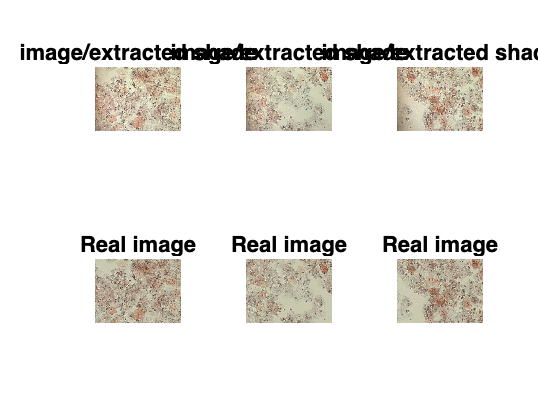

clf;
subplot(2,3,1);
imshow(1.4*new_image{1});
title('image/extracted shade');
subplot(2,3,2);
imshow(1.4*new_image{2});
title('image/extracted shade');
subplot(2,3,3);
imshow(1.4*new_image{3});
title('image/extracted shade');
subplot(2,3,4);
imshow(image_real{1});
title('Real image');
subplot(2,3,5);
imshow(image_real{2});
title('Real image');
subplot(2,3,6);
imshow(image_real{3});
title('Real image');

This part is my idea, I hypothesis that forie of shade should equal in all images, So i take fft of images and try to find part of image that equal per channles, But it isnt work.

 
% fft_image{1}=fft2(imageh{2}(:,:,1));
% fft_image{1}=fftshift(fft_image{1});
% 
% 
% fft_image{2}=fft2(imageh{1}(:,:,1));
% fft_image{2}=fftshift(fft_image{2});
% 
% A=fft_image{1}==fft_image{2};
% max(max(A))
% 
% 
% subplot(1,2,1)
% imshow(fft_image{1});
% subplot(1,2,2)
% imshow(fft_image{2});


Stich images.

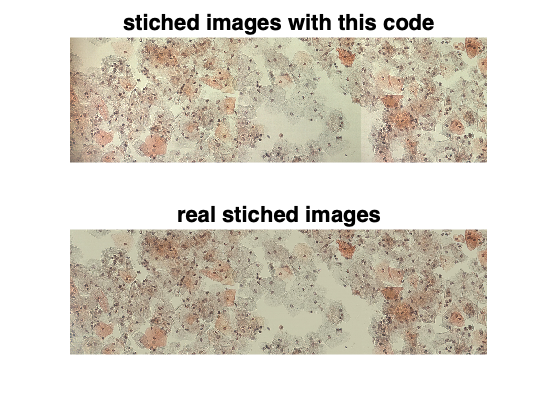

clf;
subplot(2,1,1);
imshow(uint8(1.4*[255*new_image{1},255*new_image{2}(:,605:end,:),255*new_image{3}(:,580:end,:)]));
title('stiched images with this code');
subplot(2,1,2);
imshow(uint8([image_real{1},image_real{2}(:,606:end,:),image_real{3}(:,581:end,:)]));
title('real stiched images');

toc

Elapsed time is 6.522701 seconds.
